Bridge of Doom

Theoretical Data/Calculations

syms beta t
assume(beta, {'real', 'positive'});
assume(t, {'real', 'positive'});

r_i = 4*(.3960*cos(2.65*((beta*t)+1.4)));
r_j = -4 * (.99*sin((beta*t)+1.4));
r_k = 0*t;

r = [r_i, r_j, r_k];

beta_num = .2;

r_start = double(subs(r, {beta,t},{beta_num,0}));

dr_dt = simplify(diff(r,t));
T_hat = simplify(dr_dt./norm(dr_dt));

dT_dt = simplify(diff(T_hat, t));
N_hat = simplify(dT_dt./norm(dT_dt));

t_num = linspace(0, 3.2 / beta_num, 100);
x_num = linspace(0, 3.2 / beta_num, 10);

d = 0.235;
w = simplify(cross(T_hat, dT_dt));
LS = norm(dr_dt);
VR = simplify(LS - (.5 .* (w(:,3) * d)));
VL = simplify(LS + (.5 .* (w(:,3) * d)));
WS = (VL-VR)/d;
VL_f = subs(VL, beta, beta_num);
VR_f = subs(VR, beta, beta_num);
WS_f = subs(WS, beta, beta_num);
LS_f = subs(LS, beta, beta_num);

Experimental Data/Calculations

load('bod.mat');
data = dataset(5:end,:);
time = data(:,1);
pos_l = data(:,2);
pos_r = data(:,3);
accel_x = data(:,4);
accel_y = data(:,5);
accel_z = data(:,6);

runtime = time(1:end-1);
dt = diff(time);

meas_r(1,1) = r_start(:,1);
meas_r(1,2) = r_start(:,2);

meas_vel_l = diff(pos_l)./diff(time);
meas_vel_r = diff(pos_r)./diff(time);
meas_V = .5 .*(meas_vel_l + meas_vel_r);
meas_WS = (meas_vel_r - meas_vel_l) * (1/d);

meas_t_hat = zeros(length(time)-1,2);
meas_n_hat = zeros(length(time)-1,2);


t_hat_0 = double(subs(T_hat, {beta,t},{beta_num,0}));
meas_theta(1) = atan2(t_hat_0(2), t_hat_0(1));
t_path = linspace(0, 3.2 / beta_num, length(time)-1);

Exercise 36.1

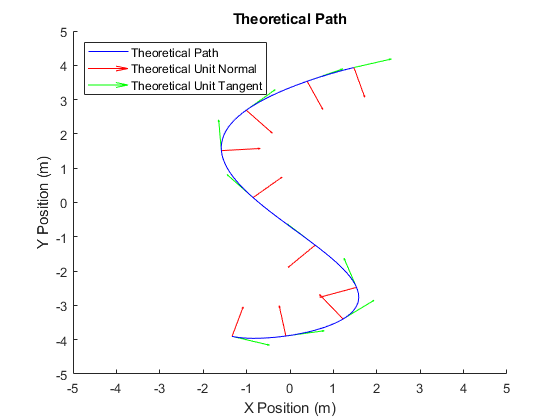

clf, figure

title('Theoretical Path')
hold on;
for n=1:length(t_num)
    r_num(n,:) = double(subs(r, {beta, t}, {beta_num, t_num(n)}));
    T_hat_num(n,:) = double(subs(T_hat, {beta, t}, {beta_num, t_num(n)}));
    N_hat_num(n,:) = double(subs(N_hat, {beta, t}, {beta_num, t_num(n)}));
    
    theo_path = plot(r_num(:,1), r_num(:,2), 'b', 'DisplayName', 'Theoretical Path'); axis([-5 5 -5 5])
    
    if (ismember(t_num(n), x_num))
        q1 = quiver(r_num(n,1), r_num(n,2), N_hat_num(n,1), N_hat_num(n,2), 'r', 'DisplayName', 'Theoretical Unit Normal');
        q2 = quiver(r_num(n,1), r_num(n,2), T_hat_num(n,1), T_hat_num(n,2), 'g', 'DisplayName', 'Theoretical Unit Tangent');
    end  
end
legend([theo_path q1 q2], 'Location', 'northwest')
xlabel('X Position (m)')
ylabel('Y Position (m)')
hold off;

Exercise 36.2

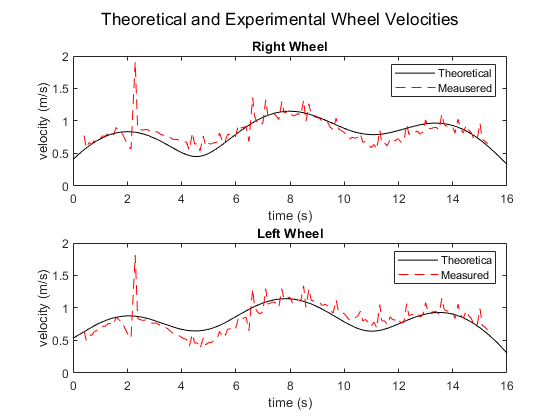

clf
fig = figure;
sgtitle('Theoretical and Experimental Wheel Velocities')
subplot(2,1,1)
fplot(VR_f,'k')
hold on, axis([0,3.2/beta_num, 0, 2]);
plot(runtime, meas_vel_r, 'r--')
title('Right Wheel')
xlabel('time (s)')
ylabel('velocity (m/s)')
legend('Theoretical', 'Meausered')
hold off;

subplot(2,1,2)
fplot(VL_f,'k')
hold on, axis([0,3.2/beta_num, 0, 2]);
plot(runtime, meas_vel_l, 'r--')
title('Left Wheel')
xlabel('time (s)')
ylabel('velocity (m/s)')
legend('Theoretica', 'Measured')

hold off; clf

Exercise 34.3

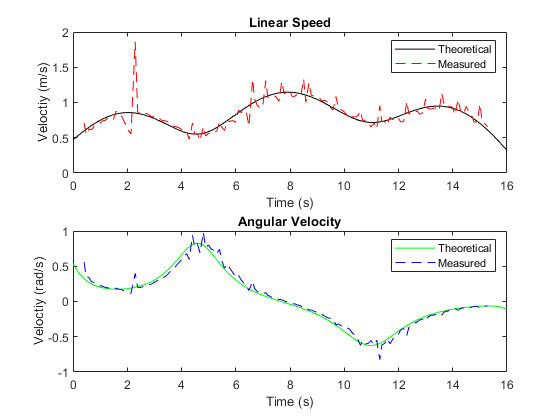

clf; figure 
subplot(2,1,1)
fplot(LS_f, 'k');
hold on, axis([0,3.2/beta_num, 0, 2]);
plot(runtime, meas_V, 'r--')
title('Linear Speed')
xlabel('Time (s)')
ylabel('Veloctiy (m/s)')
legend('Theoretical', 'Measured')
hold off;

subplot(2,1,2)
fplot(WS_f, 'g');
hold on, axis([0,3.2/beta_num, -1, 1]);
plot(runtime, meas_WS, 'b--')
title('Angular Velocity')
xlabel('Time (s)')
ylabel('Veloctiy (rad/s)')
legend('Theoretical', 'Measured')
hold off;

Exercise 36.5

for n=1:(length(time)-1)
    meas_r(n+1, 1) = meas_r(n,1) + meas_V(n)*cos(meas_theta(n))*dt(n);
    meas_r(n+1, 2) = meas_r(n,2) + meas_V(n)*sin(meas_theta(n))*dt(n);
    meas_theta(n+1) = meas_theta(n) + meas_WS(n)*dt(n);
    meas_T_hat(n,1) = cos(meas_theta(n));
    meas_T_hat(n,2) = sin(meas_theta(n));
    
    normal_adj = pi/2;
    if meas_vel_l(n) > meas_vel_r(n)
        normal_adj = -1*normal_adj;
    end
    meas_N_hat(n,1) = cos(meas_theta(n) + normal_adj);
    meas_N_hat(n,2) = sin(meas_theta(n) + normal_adj);
end  

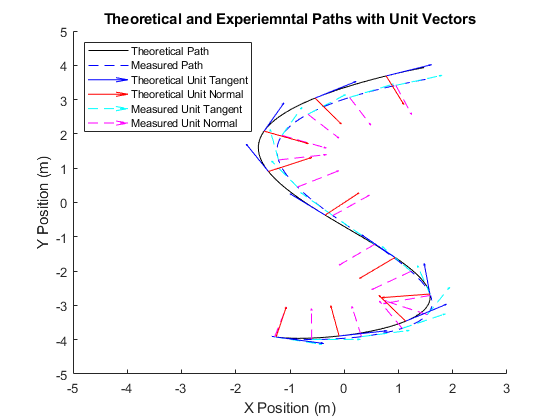

clf, figure 
hold on;
tpath = plot(r_num(:,1), r_num(:,2), 'k', 'DisplayName', 'Theoretical Path');
mpath = plot(meas_r(:,1), meas_r(:,2), 'b--', 'DisplayName', 'Measured Path');

for n=2:10:length(time)-1
    mt = quiver(meas_r(n,1), meas_r(n,2), meas_T_hat(n,1), meas_T_hat(n,2), 'c--', 'DisplayName', 'Measured Unit Tangent');
    mn = quiver(meas_r(n,1), meas_r(n,2), meas_N_hat(n,1), meas_N_hat(n,2), 'm--', 'DisplayName', 'Measured Unit Normal');
end

for n=2:10:length(t_num)
    tt = quiver(r_num(n,1), r_num(n,2), T_hat_num(n,1), T_hat_num(n,2), 'b', 'DisplayName', 'Theoretical Unit Tangent');
    tn = quiver(r_num(n,1), r_num(n,2), N_hat_num(n,1), N_hat_num(n,2), 'r', 'DisplayName', 'Theoretical Unit Normal');
end

legend([tpath mpath tt tn mt mn], 'Location', 'northwest', 'FontSize', 8)
axis([-5 3 -5 5])
title('Theoretical and Experiemntal Paths with Unit Vectors')
xlabel('X Position (m)')
ylabel('Y Position (m)')
hold off;